# Calibrating your phone's camera 

Load a certain number of images captured using your phone; detect points pixel coordinates and assigned the corresponding space ones in mm.

clear imageData
folder = 'iphone_images';
files = dir(strcat(folder, '/*.jpg'));
n = numel(files); % find number of files in folder

imageData(n,1) = struct();

squaresize = 17; % mm
chessSize = [10,11];

for i = 1:n
    imageFileName = fullfile(folder,files(i).name);
    img = imread(imageFileName); 
    % if image is not already B/N
    if length(size(img)) > 2
        img = rgb2gray(img);
    end
    
    imageData(i).I = img;

    imageData(i).XYpixel = detectCheckerboardPoints(imageData(i).I, ...
        'PartialDetections', false);  

    XYpixel = imageData(i).XYpixel;

    clear Xmm Ymm
    for j=1:length(XYpixel)
        % this function based provides the row and column position of 
        % each point on a checkerboard of the given size
        [row,col] = ind2sub(chessSize,j);
        
        % corresponding coordinates for each point in millimiters
        Xmm = (col-1)*squaresize;
        Ymm = (row-1)*squaresize;

        imageData(i).XYmm(j,:) = [Xmm, Ymm];
        
    end
end

### Estimate camera parameters using the points detected and Zhang procedure

% call the already implemented function, which can be
% found in 'utils' folder
clear data
data = estimateCamParam(imageData, n); 

### Compute reprojection error

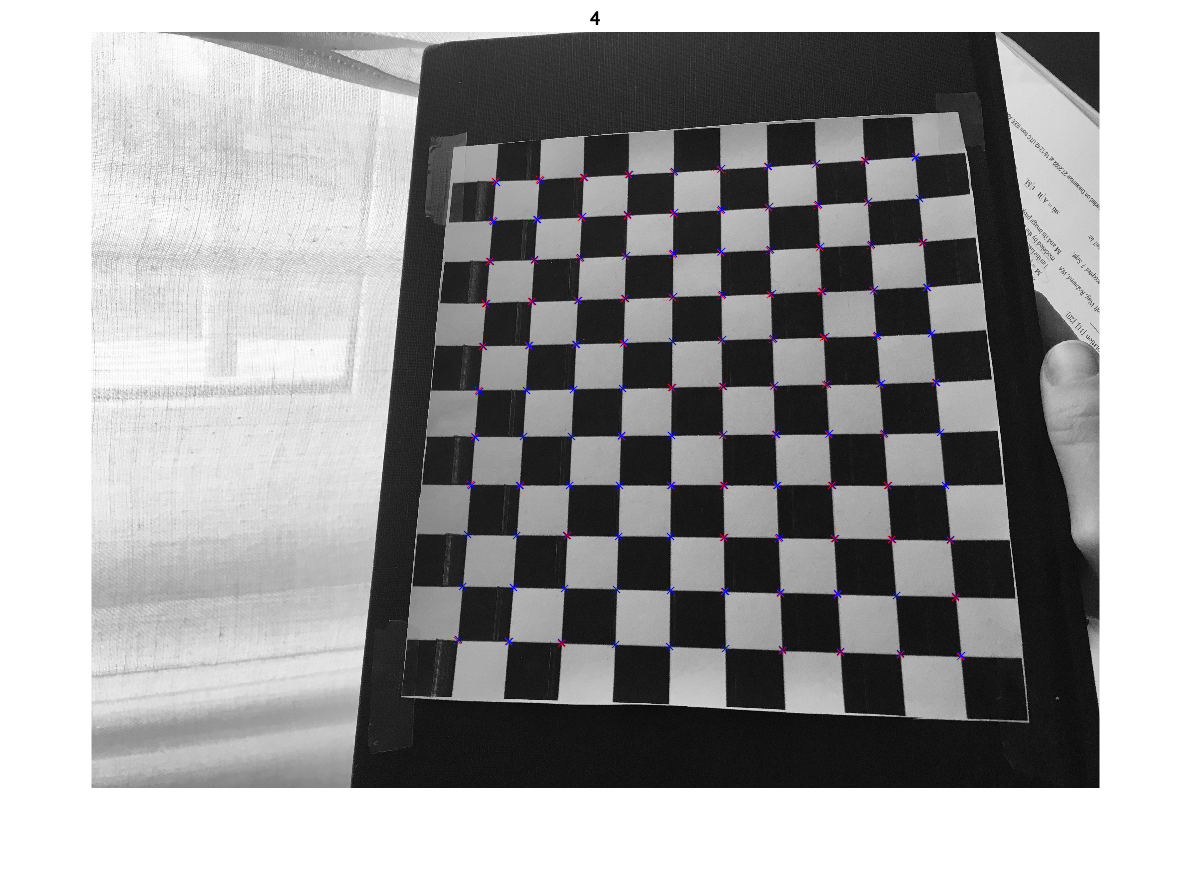

idx = 4; % choose an image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;

figure
imshow(data(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)
    
    % coordinates of point in mm
    Xmm=XYmm(i,1); 
    Ymm=XYmm(i,2);

    % 3D point m
    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;
    
    estimated_u = (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    
    % compute the error wrt visible points on the image
    Xpixel=XYpixel(i,1); 
    Ypixel=XYpixel(i,2); 
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + eu^2 + ev^2;

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

fprintf("Sum of geomtric errors is: %d", error)

Sum of geomtric errors is: 1.581407e+03

Compute the reprojection error for each image and save it in data structure.

for i=1:n
    error = 0;
    XYpixel = data(i).XYpixel;
    XYmm = data(i).XYmm;

    for j=1:length(XYpixel)
        % coordinates of point in mm
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y
    
        m = [Xmm; Ymm; 0; 1];
                
        P = data(i).P;
    
        estimated_u =  (P(1,:)*m)/(P(3,:)*m);
        estimated_v = (P(2,:)*m)/(P(3,:)*m);

        % measure error wrt points detected on keyboard by
        % detectCheckerboardPoints function
        Xpixel=XYpixel(j,1); 
        Ypixel=XYpixel(j,2); 
        eu = estimated_u - Xpixel; % error on u
        ev = estimated_v - Ypixel; % error on v
    
        error = error + eu^2 + ev^2;
    end
    data(i).error = error;
end

### Superimpose a 3D object to the calibration plane

Superimpose a cylinder to the calibration plane, in all the images employed for the calibration and obtain corresponding 2D representation.

The cylinder has center $(x_0, y_0) = (60,60)$, height $h= 50$ and radius  $r = 40$.

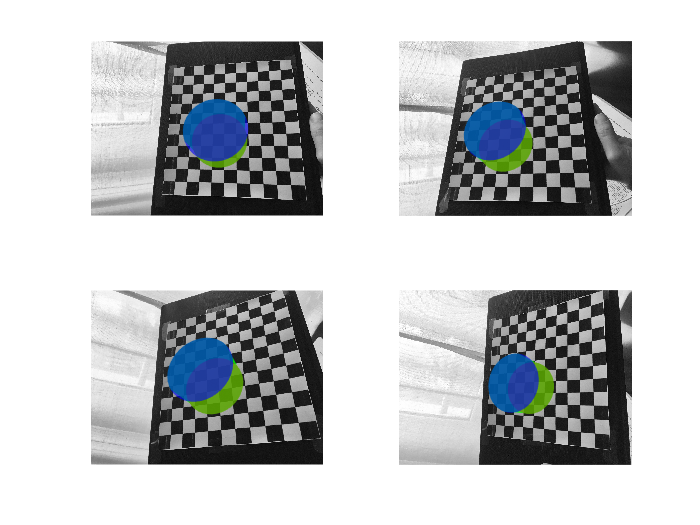

% when considering a 3D shape, we cannot use matrices Hs
% the z coordinates are not zeros and we need then to use full matrix P 

figure

for idx=4:7
    subplot(2,2,idx-3);
    imshow(data(idx).I)
    hold on
    
    % measures
    d = 80; % diameter
    r = d/2;
    h = 50; % height

    % center
    x0=60;
    y0=60;
   
    
    % points to represent the circles
    n_points = 40;
    angle = pi/n_points;  

    clear m
    % m will contain all the points of the two bases
    m = zeros(n_points*2, 4);
    for i = 1:n_points
        x = x0 + r.*cos(angle + (2*pi/n_points)*i);
        y = y0 + r.*sin(angle + (2*pi/n_points)*i);
        a = [x;y;0;1]; % point at the bottom of cylinder
        b = [x;y;h;1]; % corresponding point at top

        m(i,:) = a; % bottom basis
        m(i+n_points,:) = b; % top basis
    end

    % compute corresponding points in the image reference frame
    projected = zeros(n_points*2, 3);
    for i = 1:length(m)
        res = data(idx).P*m(i,:)';
        if res(3) > 0
            if i > n_points % only for points which have z != 0
                m(i, 3)= -h;
            end
            res = data(idx).P*m(i,:)';
            projected(i,:) = res./res(3);
        else
            projected(i,:) = res./res(3);
        end
    end

    x_bottom = projected(1:n_points,1);
    y_bottom = projected(1:n_points,2);
    x_top = projected(n_points+1:n_points*2,1);
    y_top = projected(n_points+1:n_points*2,2);
    
    % try to show the corpus of cylinder
    % find rightmost and leftmost point
    dist = zeros(n_points/2,1);
    for s=1:n_points/2
        dist(s) = sqrt((x_bottom(s) - x_bottom(s+n_points/2)).^2 + ...
            (y_bottom(s) - y_bottom(s+n_points/2)).^2); 
    end
    [~, i] = max(dist);
    k = i + n_points/2;

    if (y_bottom(i) > y_top(i) && x_bottom(i) < x_bottom(k) ) || ...
        (y_bottom(i) < y_top(i) && x_bottom(i) > x_bottom(k))
        border_x = [x_bottom(i), x_top(i:k)', x_bottom(k:end)', x_bottom(1:i-1)'];
        border_y = [y_bottom(i), y_top(i:k)', y_bottom(k:end)', y_bottom(1:i-1)'];
        
    else
        border_x = [x_top(i), x_bottom(i:k)', x_top(k:end)', x_top(1:i-1)'];
        border_y = [y_top(i), y_bottom(i:k)', y_top(k:end)', y_top(1:i-1)'];    
    end 

    patch(border_x, border_y,'green', 'LineStyle','none', ...
        'FaceColor', 'green', 'FaceAlpha', 0.8);

    % show basis
    patch(x_bottom, y_bottom, 'red', 'LineStyle','none', ...
        'FaceColor', 'red', 'FaceAlpha', 0.3);
    patch(x_top, y_top,'blue', 'LineStyle','none', ...
        'FaceColor', 'blue', 'FaceAlpha', 0.6);
    
end